# Run experiments from RAW data to position MSE error growth


pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/valento/Projects/Array-IN/experiments/joint_processing'


pathRootExp = fileparts(pathScript)

pathRootExp = '/home/valento/Projects/Array-IN/experiments'


pathData = fullfile(pathScript,"data");
mkdir(pathData);

% save(fullfile(pathData,"workspace_res.mat"),"-v7.3",  "resSingle", "resRmseMiddle","resRmseMiddleMerged", "resRmseRoll2", "resRmseRoll2Merged")
% save(fullfile(pathData,"workspace_other.mat"), '-regexp', '^(?!(resSingle|resRmseMiddle|resRmseMiddleMerged|resRmseRoll2|resRmseRoll2Merged|cost|ax|fig|ans|temp|get_)).')
% load(fullfile(pathData,"workspace_res.mat"))
% load(fullfile(pathData,"workspace_other.mat"))


% Define folder for figures
pathFigsSave = fullfile(pathScript,"figs")

pathFigsSave = "/home/valento/Projects/Array-IN/experiments/joint_processing/figs"

mkdir(pathFigsSave);


pathRoot = pathScript;
for i = 1:5
    pathRoot = fileparts(pathRoot);
end
pathRoot

pathRoot = '/home'

% pathFigsPresentation = fullfile(pathRoot, "progress", "010", "figs")
% mkdir(pathFigsPresentation);
% pathFigsPaper = fullfile(pathRoot, "paper", "IEEEtran", "figs")
foldersFigs = [pathFigsSave];

% foldersFigs = [pathFigsSave, pathFigsPresentation];
% foldersFigs = [pathFigsSave];
filePrefix = "exp_";


## Load Data

### Load MC data

serie = 2;
N_exp = 7;

data_mc = cell(7,1); 
for exp = 1:7
    
    
    file_mc = sprintf("imu-%d-000%d.mat", serie, exp);
    folder_exp = sprintf("exp%d", exp);
    load(fullfile(pathRootExp, folder_exp,"raw_data","mc",file_mc));
    
    % Load the data
    newStr = sprintf("imu_%d_000%d", serie, exp);
    data_mc_load = eval(newStr);
    
    mc_p_mm_tot = squeeze(data_mc_load.RigidBodies.Positions); % Positions in mm
    
    mc_bad_points = logical(any(isnan(mc_p_mm_tot)));
    mc_good_points = ~mc_bad_points;
    
    mc_p_tot = mc_p_mm_tot/1000;
    
    data_mc{exp}.p = mc_p_tot(:,mc_good_points);
    data_mc{exp}.time_tot = ((data_mc_load.StartFrame:data_mc_load.Frames) - 1)/data_mc_load.FrameRate;
    data_mc{exp}.time = data_mc{exp}.time_tot(mc_good_points);
    
    % The rotation matrix is from local to global, that is body to global
    data_mc{exp}.R_nb_vec_tot = squeeze(data_mc_load.RigidBodies.Rotations); % Rotation matrix
    data_mc{exp}.R_nb_vec = data_mc{exp}.R_nb_vec_tot(:,mc_good_points); % Take away nans
    data_mc{exp}.R_nb = reshape(data_mc{exp}.R_nb_vec,3,3,[]);
    data_mc{exp}.R_bn = zeros(size(data_mc{exp}.R_nb));
    
    for n = 1:size(data_mc{exp}.R_bn,3)
        data_mc{exp}.R_bn(:,:,n) = data_mc{exp}.R_nb(:,:,n)';
    end
    
    data_mc{exp}.w_nb = R2w_central_diff(data_mc{exp}.R_nb,data_mc{exp}.time);
end


### Load IMU data

data_IMU = cell(N_exp,1);
data_R0_t_shift = cell(N_exp,1);

for exp = 1:7
    folder = sprintf("exp%d", exp);
    data_IMU{exp} = load(fullfile(pathRootExp,folder,"raw_data","imu","data_same_frame.mat"));
    if exp == 1
        data_R0_t_shift{exp} = load(fullfile(pathRootExp,folder,"estimated_parameters","R0_and_tshift_v2.mat"));
    else
        data_R0_t_shift{exp} = load(fullfile(pathRootExp,folder,"estimated_parameters","R0_and_tshift.mat"));
    end
end

## Prepare data

N_sens = size(data_IMU{1}.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2)

N_imu = 32

inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);

for exp = 1:7
    data_IMU{exp}.gyro = deg2rad(data_IMU{exp}.inertial_data_double_rot(inds_gyro,:));
    data_IMU{exp}.acc = data_IMU{exp}.inertial_data_double_rot(inds_acc,:);
    data_IMU{exp}.time = data_IMU{exp}.time_stamp_corr - data_IMU{exp}.time_stamp_corr(1)-data_R0_t_shift{exp}.t_shift_opt;
end


data_IMU_mc_frame = cell(N_exp,1);
for exp = 1:7
    data_IMU_mc_frame{exp}.r0 = data_R0_t_shift{exp}.R_imu2rig_coarse*data_IMU{exp}.r0;
    R_imu2rig_coarse_tot = kron(eye(N_imu),data_R0_t_shift{exp}.R_imu2rig_coarse);
    data_IMU_mc_frame{exp}.acc = R_imu2rig_coarse_tot*data_IMU{exp}.acc;
    data_IMU_mc_frame{exp}.gyro = R_imu2rig_coarse_tot*data_IMU{exp}.gyro;
    data_IMU_mc_frame{exp}.time = data_IMU{exp}.time;
    data_IMU_mc_frame{exp}.Ts = data_IMU{exp}.Ts;
    data_IMU_mc_frame{exp}.Fs = data_IMU{exp}.Fs;
end
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

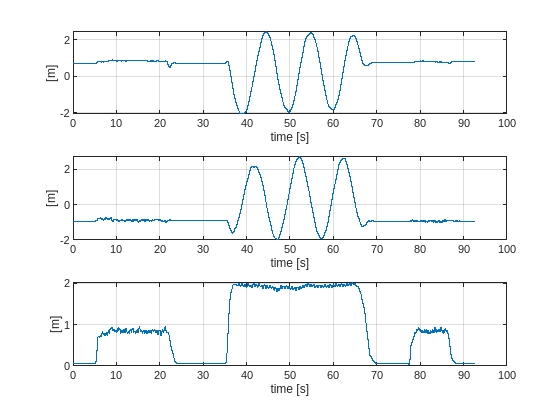


figure
exp = 7;
for i = 1:3
    subplot(3,1,i)
    plot(data_mc{exp}.time, data_mc{exp}.p(i,:))
    grid on
    xlabel("time [s]")
    ylabel("[m]")
end

No missing samples in IMU time, except in static phase of exp 1 and exp2

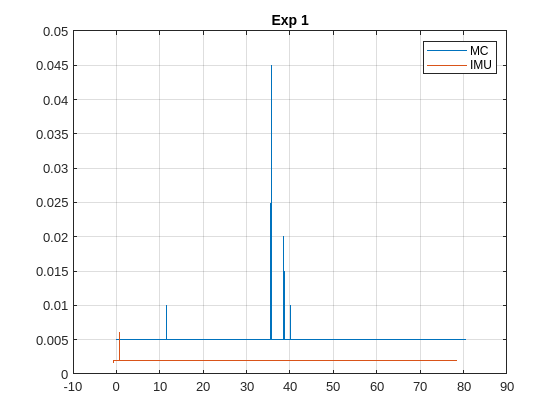

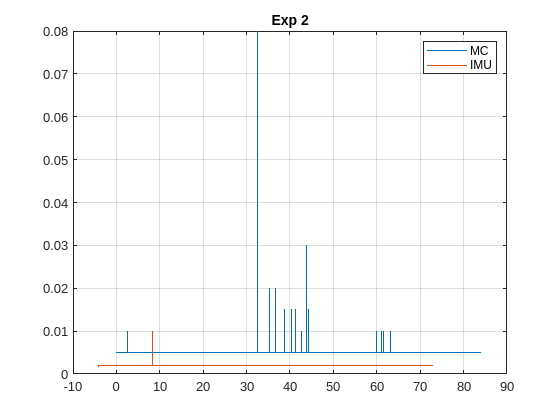

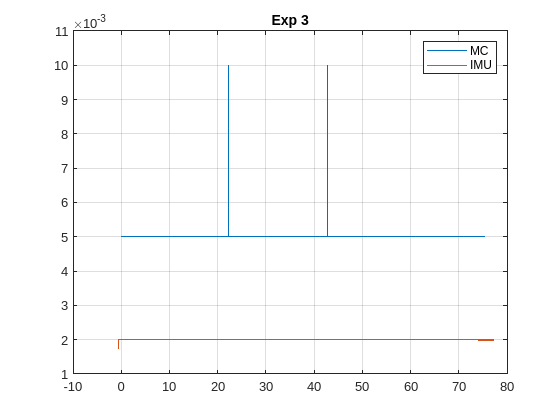

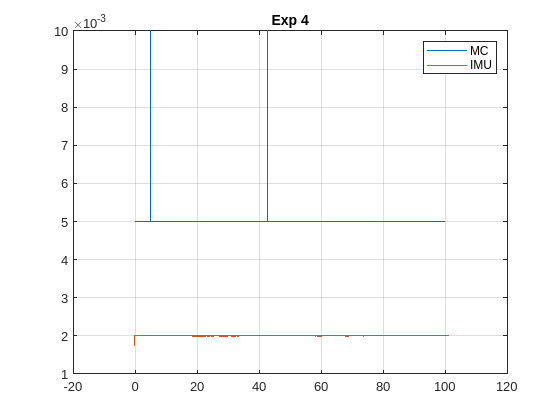

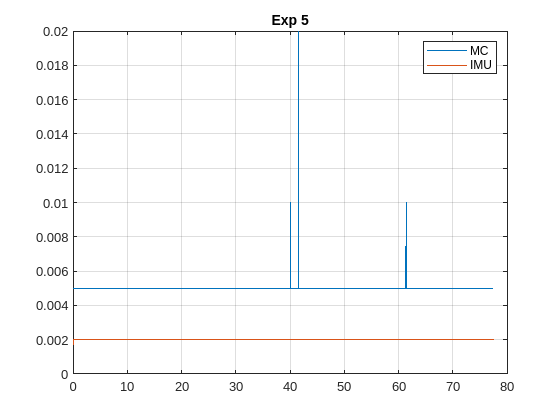

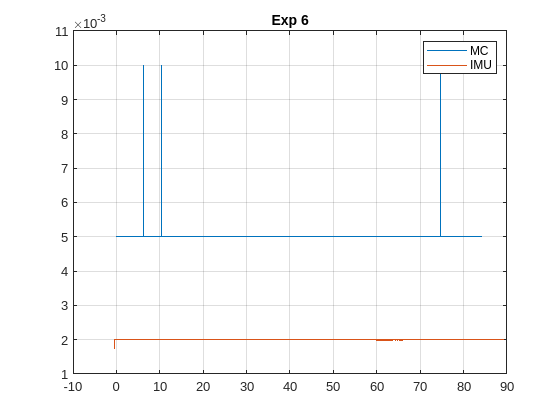

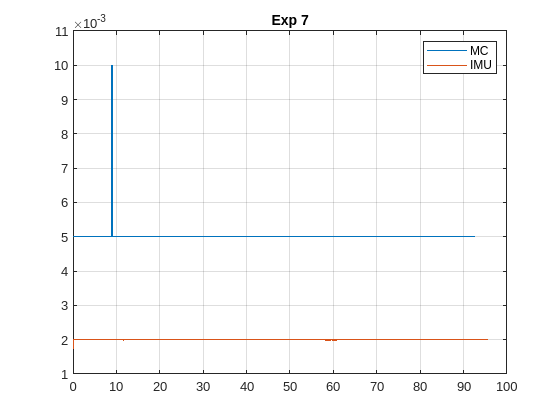


for exp = 1:7
    figure
    plot(data_mc{exp}.time(2:end), diff(data_mc{exp}.time))
    hold on
    plot(data_IMU_mc_frame{exp}.time(2:end), diff(data_IMU_mc_frame{exp}.time))
    grid on
    legend("MC", "IMU")
    title(sprintf("Exp %d", exp))
end

### Check Acc

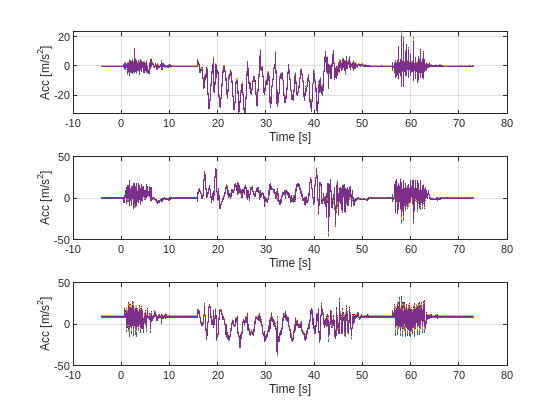

exp = 2;
figure
for i = 1:3
    subplot(3,1,i)
    title(sprintf("Exp %d", exp))
    plot(data_IMU_mc_frame{exp}.time, data_IMU_mc_frame{exp}.acc(i:3:end,:)')
    grid on
    xlabel("Time [s]")
    ylabel("Acc [m/s^2]")
end

### Check Gyro

exp = 2

exp = 2

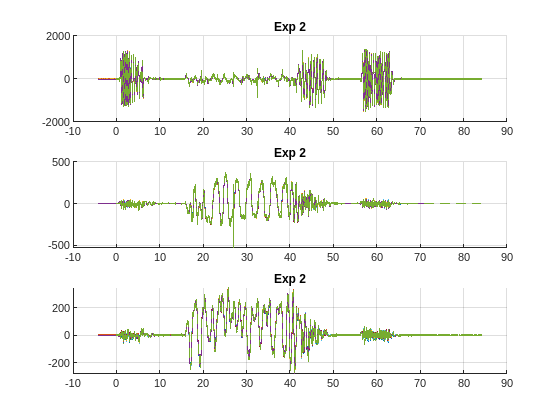

figure

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    title(sprintf("Exp %d", exp))
    plot(data_IMU_mc_frame{exp}.time, rad2deg(data_IMU_mc_frame{exp}.gyro(i:3:end,:)'))
    plot(data_mc{exp}.time, rad2deg(data_mc{exp}.w_nb(i,:)),"--")
    grid on
end

#### Slice away non overlopping times 

data_mc_sliced = cell(N_exp,1);
data_IMU_mc_frame_sliced = cell(N_exp,1);
offset_start = [0.005, 4.5e-3, 0, 0.0047, 0.03, 0.005, 0.03];
for exp = 1:7
    fprintf("Exp #%d", exp)

    fprintf("Min mc time:")
    min(data_mc{exp}.time)

    fprintf("Min IMU time:")
    min(data_IMU_mc_frame{exp}.time)
    
    fprintf("Max mc time:")
    max(data_mc{exp}.time)

    fprintf("Max IMU time:")
    max(data_IMU_mc_frame{exp}.time)

    fprintf("Max time:")
    time_max = min([max(data_mc{exp}.time),max(data_IMU_mc_frame{exp}.time)])

    fprintf("Min time:")
    time_min = offset_start(exp);
    
    mask_mc = logical( (data_mc{exp}.time >= time_min) .* (data_mc{exp}.time <= time_max));
    mask_IMU = logical( (data_IMU_mc_frame{exp}.time >= time_min) .* (data_IMU_mc_frame{exp}.time <= time_max));
    
    ind_start_mc = find(mask_mc,1);
    ind_start_imu = find(mask_IMU,1);
    t_IMU = data_IMU_mc_frame{exp}.time(mask_IMU);
    t_MC = data_mc{exp}.time(mask_mc);
    inds_imu = ind_start_imu + (-5:5);
    inds_imu = inds_imu(inds_imu>0);
    inds_mc = ind_start_mc + (-5:5);
    inds_mc = inds_mc(inds_mc>0);

    % Start at the 5th IMU sample and at the 3rd MC sample
    fprintf("Time diff:")
    t_IMU(1) - t_MC(1)
    % 0.3 ms difference    
    
    mask_mc_eff = mask_mc(1:end);
    data_mc_sliced{exp}.p = data_mc{exp}.p(:,mask_mc_eff);
    data_mc_sliced{exp}.time = data_mc{exp}.time(mask_mc_eff);
    data_mc_sliced{exp}.R_nb = data_mc{exp}.R_nb(:,:,mask_mc_eff);
    data_mc_sliced{exp}.R_bn = data_mc{exp}.R_bn(:,:,mask_mc_eff);
    data_mc_sliced{exp}.w_nb = data_mc{exp}.w_nb(:,mask_mc_eff);
    
    
    mask_IMU_eff = mask_IMU(1:end);
    data_IMU_mc_frame_sliced{exp}.acc = data_IMU_mc_frame{exp}.acc(:,mask_IMU_eff);
    data_IMU_mc_frame_sliced{exp}.gyro = data_IMU_mc_frame{exp}.gyro(:,mask_IMU_eff);
    data_IMU_mc_frame_sliced{exp}.time = data_IMU_mc_frame{exp}.time(mask_IMU_eff);
    data_IMU_mc_frame_sliced{exp}.Ts = data_IMU_mc_frame{exp}.Ts;
    data_IMU_mc_frame_sliced{exp}.Fs = data_IMU_mc_frame{exp}.Fs;
    data_IMU_mc_frame_sliced{exp}.r0 = data_IMU_mc_frame{exp}.r0;
end

Exp #1

Min mc time:

ans = 0

Min IMU time:

ans = -0.6586

Max mc time:

ans = 80.7750

Max IMU time:

ans = 78.6292

Max time:

time_max = 78.6292

Min time:

Time diff:

ans = 1.8521e-04

Exp #2

Min mc time:

ans = 0

Min IMU time:

ans = -4.1709

Max mc time:

ans = 84.1550

Max IMU time:

ans = 73.1488

Max time:

time_max = 73.1488

Min time:

Time diff:

ans = -1.7362e-04

Exp #3

Min mc time:

ans = 0

Min IMU time:

ans = -0.5676

Max mc time:

ans = 75.6400

Max IMU time:

ans = 77.2981

Max time:

time_max = 75.6400

Min time:

Time diff:

ans = 1.2179e-04

Exp #4

Min mc time:

ans = 0

Min IMU time:

ans = -0.0510

Max mc time:

ans = 100.0850

Max IMU time:

ans = 101.5267

Max time:

time_max = 100.0850

Min time:

Time diff:

ans = -2.5213e-04

Exp #5

Min mc time:

ans = 0

Min IMU time:

ans = 0.0226

Max mc time:

ans = 77.4550

Max IMU time:

ans = 77.6683

Max time:

time_max = 77.4550

Min time:

Time diff:

ans = 3.4450e-04

Exp #6

Min mc time:

ans = 0

Min IMU time:

ans = -0.4602

Max mc time:

ans = 84.4450

Max IMU time:

ans = 89.3956

Max time:

time_max = 84.4450

Min time:

Time diff:

ans = 5.9356e-04

Exp #7

Min mc time:

ans = 0

Min IMU time:

ans = 0.0268

Max mc time:

ans = 92.8550

Max IMU time:

ans = 95.7545

Max time:

time_max = 92.8550

Min time:

Time diff:

ans = 5.3074e-04

data_IMU_mc_frame_sliced_100Hz = cell(N_exp,1);
for exp = 1:7
    Nt = length(data_IMU_mc_frame_sliced{exp}.time);
    data_IMU_mc_frame_sliced_100Hz{exp}.time = data_IMU_mc_frame_sliced{exp}.time(1:5:Nt);
    data_IMU_mc_frame_sliced_100Hz{exp}.acc = data_IMU_mc_frame_sliced{exp}.acc(:,1:5:Nt);
    data_IMU_mc_frame_sliced_100Hz{exp}.gyro = data_IMU_mc_frame_sliced{exp}.gyro(:,1:5:Nt);

    data_IMU_mc_frame_sliced_100Hz{exp}.Ts = data_IMU_mc_frame{exp}.Ts*5;
    data_IMU_mc_frame_sliced_100Hz{exp}.Fs = data_IMU_mc_frame{exp}.Fs/5;
    data_IMU_mc_frame_sliced_100Hz{exp}.r0 = data_IMU_mc_frame{exp}.r0;
end

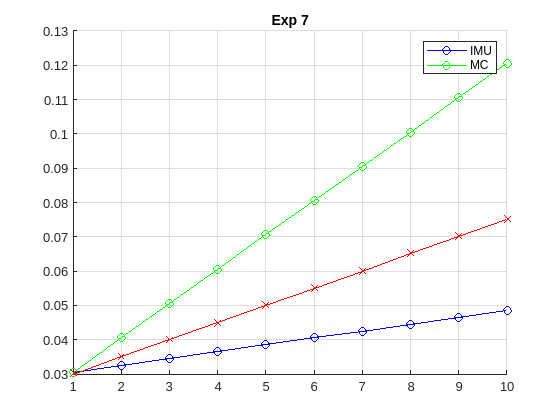

exp = 7;
figure;
hold on
plot(data_IMU_mc_frame_sliced{exp}.time(1:10),"-ob")
plot(data_IMU_mc_frame_sliced_100Hz{exp}.time(1:10),"-og")
plot(data_mc_sliced{exp}.time(1:10),"-xr")
% plot(t_MC(1:10),"-x")
grid on
legend("IMU","MC")
title(sprintf("Exp %d", exp))

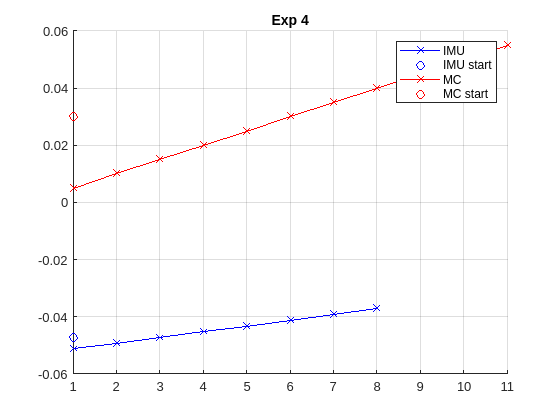

exp = 4;
figure;
hold on
plot(data_IMU_mc_frame{exp}.time(inds_imu),"-xb")
plot(data_IMU_mc_frame{exp}.time(ind_start_imu),"ob")
plot(data_mc{exp}.time(inds_mc),"-xr")
plot(data_mc{exp}.time(ind_start_mc ),"or")
% plot(t_MC(1:10),"-x")
grid on
legend("IMU","IMU start", "MC", "MC start")
title(sprintf("Exp %d", exp))

### MC positions in IMU time 

Downsample position updates to 100 Hz in updates

for exp = 1:N_exp
    Nt_IMU = length(data_IMU_mc_frame_sliced{exp}.time);
    data_IMU_mc_frame_sliced{exp}.p_rig_update = nan(3,Nt_IMU);
    inds_pos_update = 1:5:Nt_IMU;
    data_IMU_mc_frame_sliced{exp}.p_rig_update(:,inds_pos_update) = interp1(data_mc{exp}.time, data_mc{exp}.p', data_IMU_mc_frame_sliced{exp}.time(inds_pos_update))';
    data_IMU_mc_frame_sliced{exp}.p_rig = interp1(data_mc{exp}.time, data_mc{exp}.p', data_IMU_mc_frame_sliced{exp}.time)';
    
end

for exp = 1:N_exp
    Nt_IMU = length(data_IMU_mc_frame_sliced_100Hz{exp}.time);
    data_IMU_mc_frame_sliced_100Hz{exp}.p_rig_update = nan(3,Nt_IMU);
    inds_pos_update = 1:Nt_IMU;
    data_IMU_mc_frame_sliced_100Hz{exp}.p_rig_update(:,inds_pos_update) = interp1(data_mc{exp}.time, data_mc{exp}.p', data_IMU_mc_frame_sliced_100Hz{exp}.time(inds_pos_update))';
    data_IMU_mc_frame_sliced_100Hz{exp}.p_rig = interp1(data_mc{exp}.time, data_mc{exp}.p', data_IMU_mc_frame_sliced_100Hz{exp}.time)';
    
end

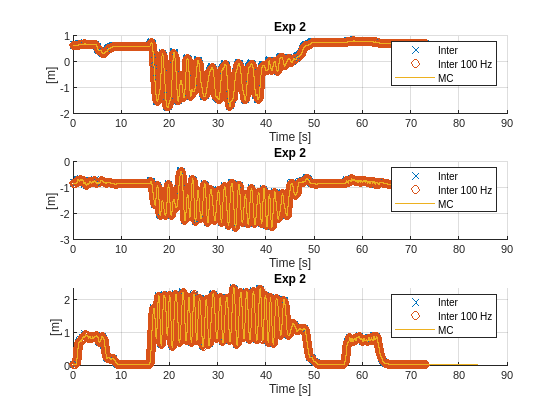

exp = 2;
figure
for i = 1:3
    subplot(3,1,i); hold on
    title(sprintf("Exp %d", exp))
    plot(data_IMU_mc_frame_sliced{exp}.time, data_IMU_mc_frame_sliced{exp}.p_rig(i,:),"x")
    plot(data_IMU_mc_frame_sliced_100Hz{exp}.time, data_IMU_mc_frame_sliced_100Hz{exp}.p_rig(i,:),"o")
    plot(data_mc{exp}.time, data_mc{exp}.p(i,:),"-")
    grid on
    xlabel("Time [s]")
    ylabel("[m]")
    legend("Inter","Inter 100 Hz", "MC")
end

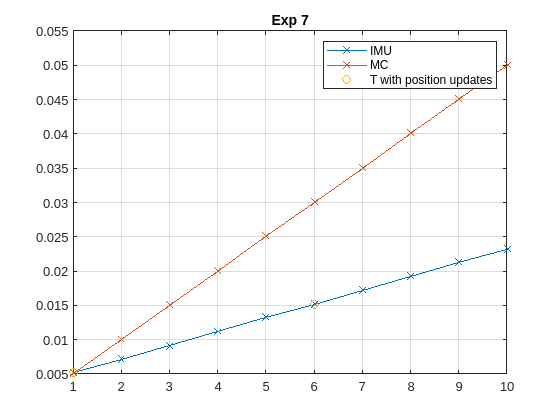

exp = 7;
figure;
N_points = 10;
plot(data_IMU_mc_frame_sliced{1}.time(1:N_points),"-x")
hold on
plot(data_mc_sliced{1}.time(1:N_points),"-x")
plot(1:5:N_points,data_IMU_mc_frame_sliced{1}.time(1:5:N_points),"o")
title(sprintf("Exp %d", exp))
grid on
legend("IMU","MC", "T with position updates")

#### MC rotation in in IMU time 500 Hz

for exp = 1:N_exp
    data_IMU_mc_frame_sliced{exp}.R_nb_rig = interpolate_rotation(data_mc{exp}.time, data_mc{exp}.R_nb, data_IMU_mc_frame_sliced{exp}.time);
    % data_IMU_mc_frame_sliced{exp}.R_nb_rig_update = nan(size(data_IMU_mc_frame_sliced{exp}.R_nb_rig));
    % data_IMU_mc_frame_sliced{exp}.R_nb_rig_update(:,:,inds_pos_update) = interpolate_rotation(data_mc{exp}.time, data_mc{exp}.R_nb, data_IMU_mc_frame_sliced{exp}.time(inds_pos_update));
    % z-y′-x″ (intrinsic rotations) or x-y-z (extrinsic rotations):
    % the intrinsic rotations are known as: yaw, pitch and roll
    data_IMU_mc_frame_sliced{exp}.euler_rig = my_rotm2eul(data_IMU_mc_frame_sliced{exp}.R_nb_rig);
    data_mc{exp}.euler = my_rotm2eul(data_mc{exp}.R_nb);
    

end

Roll around x-axis

#### MC rotation in in IMU time 100 Hz

for exp = 1:N_exp
    data_IMU_mc_frame_sliced_100Hz{exp}.R_nb_rig = interpolate_rotation(data_mc{exp}.time, data_mc{exp}.R_nb, data_IMU_mc_frame_sliced_100Hz{exp}.time);
    % data_IMU_mc_frame_sliced{exp}.R_nb_rig_update = nan(size(data_IMU_mc_frame_sliced{exp}.R_nb_rig));
    % data_IMU_mc_frame_sliced{exp}.R_nb_rig_update(:,:,inds_pos_update) = interpolate_rotation(data_mc{exp}.time, data_mc{exp}.R_nb, data_IMU_mc_frame_sliced{exp}.time(inds_pos_update));
    % z-y′-x″ (intrinsic rotations) or x-y-z (extrinsic rotations):
    % the intrinsic rotations are known as: yaw, pitch and roll
    data_IMU_mc_frame_sliced_100Hz{exp}.euler_rig = my_rotm2eul(data_IMU_mc_frame_sliced_100Hz{exp}.R_nb_rig);
    

end

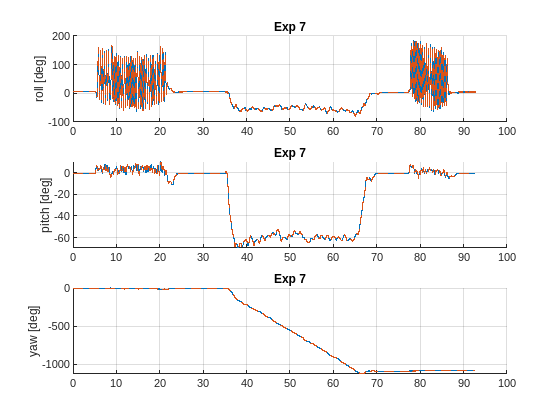

exp = 7;
figure
dirs_angle = ["roll", "pitch", "yaw",];
for i = 1:3
    subplot(3,1,i); hold on
    title(sprintf("Exp %d", exp))
    plot(data_mc{exp}.time,rad2deg(data_mc{exp}.euler(i,:)))
    plot(data_IMU_mc_frame_sliced{exp}.time, rad2deg(data_IMU_mc_frame_sliced{exp}.euler_rig(i,:)),"--")
    grid on
    ylabel(sprintf("% s [deg]", dirs_angle(i)))
end
title(sprintf("Exp %d", exp))

#### Define array filter settings

N_imu = size(data_IMU_mc_frame{1}.r0,2);
settings_default = struct;
settings_default.T = data_IMU_mc_frame{1}.Ts;
settings_default.g = gravity(58.41,0);
settings_default.r = data_IMU_mc_frame{1}.r0;
settings_default.N_a = size(data_IMU_mc_frame{1}.r0,2);
settings_default.N_g = 1;
settings_default.verbose = true;
settings_default.g

ans =          0
         0
   -9.8179


#### Define filter sigmas

parameters_coarse = struct;
parameters_coarse.sig_acc = 0.5 % Acc noise

parameters_coarse = struct with fields:
    sig_acc: 0.5000


parameters_coarse.sig_gyro = deg2rad(1) % gyro noise

parameters_coarse = struct with fields:
     sig_acc: 0.5000
    sig_gyro: 0.0175



parameters_coarse.sig_init_b_a = parameters_coarse.sig_acc*2; %m/s^2
parameters_coarse.sig_init_b_g = deg2rad(1)*2; % [rad/s]
parameters_coarse.sig_b_a = 1e-7;
parameters_coarse.sig_b_g = deg2rad(1e-7);

% MC system 
parameters_coarse.sig_pos = 1e-1; % Sigma position update
parameters_coarse.sig_rot = deg2rad(1); % sigma rotation update


for exp = 1:N_exp
    data_IMU_mc_frame_sliced{exp}.gyro_mean = triad_mean(data_IMU_mc_frame_sliced{exp}.gyro);
    data_IMU_mc_frame_sliced{exp}.acc_mean = triad_mean(data_IMU_mc_frame_sliced{exp}.acc);
end

for exp = 1:N_exp
    data_IMU_mc_frame_sliced_100Hz{exp}.gyro_mean = triad_mean(data_IMU_mc_frame_sliced_100Hz{exp}.gyro);
    data_IMU_mc_frame_sliced_100Hz{exp}.acc_mean = triad_mean(data_IMU_mc_frame_sliced_100Hz{exp}.acc);
end

## Make figure of dynamics


fig = figure;
hold on
for i = 1:3
    % ax(i) = subplot(3,1,i); hold on
    plot(data_IMU_mc_frame_sliced{1}.time, rad2deg(data_IMU_mc_frame_sliced{1}.gyro_mean(i,:)'))

end
yLim = ylim;
y_patch = [yLim(2) yLim(2) yLim(1) yLim(1)];
get_x_path = @(s,e) [s e e s] ;
patch(get_x_path(4.7, 16), y_patch, "b" , "FaceAlpha", 0.2)
patch(get_x_path(22.3, 51.9), y_patch, "r" , "FaceAlpha", 0.2)
patch(get_x_path(60.9, 69.5), y_patch, "g" , "FaceAlpha", 0.2)
grid on
ylabel("[deg/s]")
xlabel("Time [s]")
xlim([0,70])
legend("x","y","z","Time-sync phase", "Low dynamicss","High dynamics", "Location","north")
printpdf_multiple(fig, filePrefix + "gyro_mean.pdf", foldersFigs)


% title(sprintf("Exp %d", exp))

pathDataFigsPaperMotion = fullfile(pathScript,"data_figs_paper_motion")

pathDataFigsPaperMotion = "/home/valento/Projects/Array-IN/experiments/joint_processing/data_figs_paper_motion"

mkdir(pathDataFigsPaperMotion)


resPlotMotion = struct;
resPlotMotion.w_b = data_IMU_mc_frame_sliced{1}.gyro_mean;
resPlotMotion.t = data_IMU_mc_frame_sliced{1}.time;

save(fullfile(pathDataFigsPaperMotion,"data.mat"), "-struct", "resPlotMotion")

### Initial Values 


init = cell(N_exp,1);

for exp = 1:N_exp
    fprintf("Exp #%d", exp)
    data_IMU_mc_frame_sliced{exp}.acc_mean(:,1:20)
    
    [roll, pitch] = stationaryAcc2rollPitch(data_IMU_mc_frame_sliced{exp}.acc_mean(:,1:20))
    % IS is up side down
    rad2deg(roll)
    rad2deg(pitch)
    R_start = average_rotation(data_IMU_mc_frame_sliced{exp}.R_nb_rig(:,:,1:20));
    % Yaw, pitch, roll
    euler_start = rad2deg(rotm2eul(R_start))
    R_bn_start = R_start'
    R_bn_start*-settings_default.g
    mean(data_IMU_mc_frame_sliced{exp}.acc_mean(:,1:20),2)

    init{exp}.mean.R = R_start;
    init{exp}.mean.omega = data_IMU_mc_frame_sliced{exp}.gyro_mean(:,1);
    init{exp}.mean.p = data_IMU_mc_frame_sliced{exp}.p_rig(:,1);
    init{exp}.mean.v = zeros(3,1);
    init{exp}.mean.b_a = zeros(3*N_imu,1);
    init{exp}.mean.b_g = zeros(3,1);
    
    init{exp}.cov.R = eye(3)*deg2rad(1)^2;
    init{exp}.cov.omega = parameters_coarse.sig_gyro^2*eye(3)/N_imu*3;
    init{exp}.cov.p = parameters_coarse.sig_pos^2*eye(3)*3;
    init{exp}.cov.v = eye(3)*(1e-2)^2;
    init{exp}.cov.b_a = parameters_coarse.sig_acc^2*eye(3*N_imu)*3;
    init{exp}.cov.b_g = parameters_coarse.sig_gyro^2*eye(3)/N_imu*3;

end

Exp #1

ans =    -0.0241   -0.0235   -0.0229   -0.0260   -0.0220   -0.0271   -0.0272   -0.0230   -0.0157   -0.0127   -0.0296   -0.0139   -0.0066   -0.0202   -0.0138   -0.0320   -0.0105   -0.0066   -0.0220   -0.0111
    0.3724    0.3778    0.3663    0.3810    0.3825    0.3777    0.3724    0.3816    0.3757    0.3739    0.3793    0.3759    0.3692    0.3648    0.3793    0.3744    0.3783    0.3771    0.3801    0.3910
    9.7589    9.7670    9.7537    9.7610    9.7552    9.7668    9.7728    9.7835    9.7730    9.7532    9.7576    9.7576    9.7552    9.7583    9.7627    9.7588    9.7591    9.7484    9.7489    9.7514


roll = 0.0020

pitch = 0.0386

ans = 0.1146

ans = 2.2093

1/20: tol: 5.503e-04 / 1.000e-10
2/20: tol: 2.005e-12 / 1.000e-10


euler_start =    -1.4904   -1.0417    4.9176


R_bn_start =     0.9995   -0.0260    0.0182
    0.0244    0.9960    0.0857
   -0.0203   -0.0852    0.9962


ans =     0.1785
    0.8415
    9.7802


ans =    -0.0195
    0.3765
    9.7602


Exp #2

ans =     0.0190    0.0124    0.0211    0.0314    0.0241    0.0323    0.0127    0.0180    0.0165    0.0169    0.0277    0.0262    0.0120    0.0319    0.0165    0.0159    0.0184    0.0121    0.0073    0.0174
    0.4338    0.4383    0.4298    0.4335    0.4286    0.4482    0.4296    0.4363    0.4444    0.4245    0.4226    0.4350    0.4396    0.4371    0.4214    0.4389    0.4351    0.4416    0.4374    0.4353
    9.7981    9.7962    9.7935    9.7879    9.8013    9.7805    9.7820    9.7995    9.8029    9.7945    9.7998    9.8146    9.8034    9.8019    9.8173    9.8071    9.8013    9.8222    9.8049    9.8058


roll = -0.0020

pitch = 0.0443

ans = -0.1139

ans = 2.5387

1/20: tol: 2.804e-04 / 1.000e-10
2/20: tol: 2.208e-12 / 1.000e-10


euler_start =     4.0577   -1.1384    5.1538


R_bn_start =     0.9973    0.0707    0.0199
   -0.0723    0.9933    0.0898
   -0.0134   -0.0910    0.9958


ans =     0.1951
    0.8818
    9.7763


ans =     0.0195
    0.4345
    9.8007


Exp #3

ans =     0.0100   -0.0063    0.0181    0.0154    0.0003    0.0111    0.0040    0.0148    0.0192    0.0093    0.0151    0.0118    0.0106    0.0178    0.0097    0.0073    0.0102   -0.0016    0.0171    0.0127
    0.3660    0.3582    0.3678    0.3599    0.3554    0.3627    0.3470    0.3537    0.3627    0.3479    0.3630    0.3515    0.3588    0.3599    0.3506    0.3582    0.3449    0.3555    0.3460    0.3599
    9.7902    9.7905    9.8204    9.8230    9.7992    9.7986    9.8055    9.8035    9.8074    9.7873    9.7812    9.7924    9.8098    9.7930    9.7948    9.8016    9.8195    9.7827    9.8037    9.7963


roll = -0.0011

pitch = 0.0364

ans = -0.0604

ans = 2.0833

1/20: tol: 4.885e-04 / 1.000e-10
2/20: tol: 8.040e-12 / 1.000e-10


euler_start =    -2.1112   -1.0065    4.6575


R_bn_start =     0.9992   -0.0368    0.0176
    0.0353    0.9961    0.0812
   -0.0205   -0.0805    0.9965


ans =     0.1725
    0.7971
    9.7840


ans =     0.0103
    0.3565
    9.8000


Exp #4

ans =     0.0325    0.0374    0.0443    0.0419    0.0434    0.0464    0.0308    0.0528    0.0453    0.0400    0.0268    0.0356    0.0319    0.0350    0.0304    0.0350    0.0289    0.0371    0.0420    0.0394
    0.5987    0.6030    0.6036    0.6081    0.5932    0.6110    0.6072    0.5956    0.6021    0.6017    0.6143    0.5988    0.6023    0.5962    0.5956    0.6092    0.6098    0.5954    0.6039    0.6047
    9.7981    9.7924    9.7830    9.7962    9.8093    9.8032    9.7990    9.8110    9.8061    9.8029    9.7879    9.7882    9.7956    9.7944    9.7888    9.7863    9.7968    9.8019    9.7956    9.7942


roll = -0.0039

pitch = 0.0614

ans = -0.2213

ans = 3.5206

1/20: tol: 5.017e-05 / 1.000e-10
2/20: tol: 7.294e-13 / 1.000e-10


euler_start =     2.9576   -1.1482    5.9736


R_bn_start =     0.9985    0.0516    0.0200
   -0.0534    0.9931    0.1040
   -0.0145   -0.1050    0.9944


ans =     0.1967
    1.0215
    9.7626


ans =     0.0378
    0.6027
    9.7965


Exp #5

ans =     0.0144    0.0123    0.0109    0.0036    0.0166    0.0108    0.0171    0.0292    0.0090    0.0286    0.0269    0.0103    0.0192    0.0211    0.0130    0.0257    0.0209    0.0175    0.0196    0.0085
    0.4052    0.3989    0.3937    0.4060    0.4120    0.3995    0.3915    0.3888    0.3916    0.4003    0.3986    0.3986    0.4028    0.3982    0.4015    0.4004    0.4099    0.4073    0.3876    0.3958
    9.8017    9.8032    9.8050    9.8137    9.8022    9.8052    9.8056    9.8140    9.8119    9.8137    9.8113    9.8078    9.8123    9.8158    9.8016    9.8195    9.8059    9.8251    9.8171    9.8052


roll = -0.0017

pitch = 0.0407

ans = -0.0979

ans = 2.3315

1/20: tol: 1.971e-04 / 1.000e-10
2/20: tol: 1.927e-12 / 1.000e-10


euler_start =    -4.5603   -1.0159    4.8841


R_bn_start =     0.9967   -0.0795    0.0177
    0.0777    0.9933    0.0851
   -0.0244   -0.0835    0.9962


ans =     0.1741
    0.8358
    9.7807


ans =     0.0168
    0.3994
    9.8099


Exp #6

ans =     0.0320    0.0488    0.0233    0.0153    0.0196    0.0114    0.0127    0.0048   -0.0045    0.0100   -0.0004    0.0051    0.0004   -0.0118    0.0103    0.0233    0.0055    0.0215    0.0057    0.0206
    0.5417    0.5225    0.5858    0.4856    0.5332    0.5019    0.5861    0.5146    0.5324    0.5043    0.5813    0.5348    0.5558    0.5303    0.5686    0.5562    0.5454    0.5101    0.5468    0.5552
    9.7600    9.7662    9.8040    9.7927    9.7945    9.7809    9.7833    9.7924    9.8263    9.8069    9.7951    9.7888    9.8098    9.8189    9.8074    9.8222    9.7950    9.8152    9.8035    9.8295


roll = -0.0013

pitch = 0.0550

ans = -0.0742

ans = 3.1519

1/20: tol: 4.009e-04 / 1.000e-10
2/20: tol: 3.128e-12 / 1.000e-10


euler_start =    -0.9946   -1.1015    5.6438


R_bn_start =     0.9997   -0.0174    0.0192
    0.0154    0.9950    0.0983
   -0.0208   -0.0980    0.9950


ans =     0.1887
    0.9653
    9.7685


ans =     0.0127
    0.5396
    9.7996


Exp #7

ans =     0.0329    0.0304    0.0271    0.0229    0.0305    0.0280    0.0438    0.0386    0.0338    0.0368    0.0322    0.0274    0.0513    0.0323    0.0359    0.0313    0.0314    0.0337    0.0356    0.0310
    0.5174    0.5362    0.5288    0.5270    0.5363    0.5330    0.5300    0.5293    0.5408    0.5312    0.5154    0.5179    0.5225    0.5348    0.5240    0.5240    0.5273    0.5249    0.5261    0.5303
    9.8078    9.8019    9.7830    9.8114    9.8046    9.7957    9.7906    9.7992    9.8001    9.8156    9.8053    9.8132    9.8110    9.8114    9.8174    9.8096    9.8090    9.8113    9.8083    9.7980


roll = -0.0034

pitch = 0.0538

ans = -0.1949

ans = 3.0816

1/20: tol: 6.131e-04 / 1.000e-10
2/20: tol: 5.120e-12 / 1.000e-10


euler_start =    -9.3504   -1.0722    5.5551


R_bn_start =     0.9865   -0.1624    0.0187
    0.1599    0.9824    0.0968
   -0.0341   -0.0925    0.9951


ans =     0.1837
    0.9502
    9.7701


ans =     0.0333
    0.5279
    9.8052


% assert(false)

## Run Filters raw measurements

S_ref = cell(N_exp,1);
for exp = 1:N_exp
    S_ref{exp}.p = data_IMU_mc_frame_sliced{exp}.p_rig;
    S_ref{exp}.R = data_IMU_mc_frame_sliced{exp}.R_nb_rig;
end

S_ref_100Hz = cell(N_exp,1);
for exp = 1:N_exp
    S_ref_100Hz{exp}.p = data_IMU_mc_frame_sliced_100Hz{exp}.p_rig;
    S_ref_100Hz{exp}.R = data_IMU_mc_frame_sliced_100Hz{exp}.R_nb_rig;
end

### Models

simdata = struct;

simdata.coarse.accelerometer_array_2nd_order = settings_default;
simdata.coarse.accelerometer_array_2nd_order.propagate_position = true;
simdata.coarse.accelerometer_array_2nd_order.propagate_velocity = true;
simdata.coarse.accelerometer_array_2nd_order.propagate_bias_alpha = true;
simdata.coarse.accelerometer_array_2nd_order.propagate_bias_gyro = true;
simdata.coarse.accelerometer_array_2nd_order.set_T2_R_zero = false;
simdata.coarse.accelerometer_array_2nd_order.get_model = @D_LG_EKF_Array_v4_alpha;
simdata.coarse.accelerometer_array_2nd_order.r = data_IMU_mc_frame_sliced{1}.r0;
simdata.coarse.accelerometer_array_2nd_order.Q_acc = parameters_coarse.sig_acc^2*eye(3*N_imu);
simdata.coarse.accelerometer_array_2nd_order.Q_bias_acc = parameters_coarse.sig_b_a^2*eye(3*N_imu);
simdata.coarse.accelerometer_array_2nd_order.R_pos = parameters_coarse.sig_pos^2*eye(3);
simdata.coarse.accelerometer_array_2nd_order.R_rot = parameters_coarse.sig_rot^2*eye(3);
simdata.coarse.accelerometer_array_2nd_order.R_gyro = parameters_coarse.sig_gyro^2*eye(3)/N_imu;
simdata.coarse.accelerometer_array_2nd_order.Q_bias_gyro = parameters_coarse.sig_b_g^2*eye(3)/N_imu;
simdata.coarse.accelerometer_array_2nd_order.do_gyro_updates = true;
simdata.coarse.accelerometer_array_2nd_order.do_position_updates = true;
simdata.coarse.accelerometer_array_2nd_order.do_rotation_updates = false;
simdata.coarse.accelerometer_array_2nd_order.label = "2nd order accelerometer array";


simdata.coarse.accelerometer_array_1st_order = settings_default;
simdata.coarse.accelerometer_array_1st_order.propagate_position = true;
simdata.coarse.accelerometer_array_1st_order.propagate_velocity = true;
simdata.coarse.accelerometer_array_1st_order.propagate_bias_alpha = true;
simdata.coarse.accelerometer_array_1st_order.propagate_bias_gyro = true;
simdata.coarse.accelerometer_array_1st_order.set_T2_R_zero = true;
simdata.coarse.accelerometer_array_1st_order.get_model = @D_LG_EKF_Array_v4_alpha;
simdata.coarse.accelerometer_array_1st_order.r = data_IMU_mc_frame_sliced{1}.r0;
simdata.coarse.accelerometer_array_1st_order.Q_acc = parameters_coarse.sig_acc^2*eye(3*N_imu);
simdata.coarse.accelerometer_array_1st_order.Q_bias_acc = parameters_coarse.sig_b_a^2*eye(3*N_imu);
simdata.coarse.accelerometer_array_1st_order.R_pos = parameters_coarse.sig_pos^2*eye(3);
simdata.coarse.accelerometer_array_1st_order.R_rot = parameters_coarse.sig_rot^2*eye(3);
simdata.coarse.accelerometer_array_1st_order.R_gyro = parameters_coarse.sig_gyro^2*eye(3);
simdata.coarse.accelerometer_array_1st_order.Q_bias_gyro = parameters_coarse.sig_b_g^2*eye(3)/N_imu;
simdata.coarse.accelerometer_array_1st_order.do_gyro_updates = true;
simdata.coarse.accelerometer_array_1st_order.do_position_updates = true;
simdata.coarse.accelerometer_array_1st_order.do_rotation_updates = false;
simdata.coarse.accelerometer_array_1st_order.label = "1st order accelerometer array";

simdata.coarse.gyroscope_2nd_order = settings_default;
simdata.coarse.gyroscope_2nd_order.propagate_bias_gyro = true;
simdata.coarse.gyroscope_2nd_order.input_accelerometers = true;
simdata.coarse.gyroscope_2nd_order.propagate_position = true;
simdata.coarse.gyroscope_2nd_order.propagate_velocity = true;
simdata.coarse.gyroscope_2nd_order.propagate_bias_s = true;
simdata.coarse.gyroscope_2nd_order.set_T2_R_zero = false;
simdata.coarse.gyroscope_2nd_order.get_model = @D_LG_EKF_Gyro_2nd_v4;
simdata.coarse.gyroscope_2nd_order.r = data_IMU_mc_frame_sliced{1}.r0;
simdata.coarse.gyroscope_2nd_order.Q_acc = parameters_coarse.sig_acc^2*eye(3*N_imu);
simdata.coarse.gyroscope_2nd_order.Q_bias_acc = parameters_coarse.sig_b_a^2*eye(3*N_imu);
simdata.coarse.gyroscope_2nd_order.R_pos = parameters_coarse.sig_pos^2*eye(3);
simdata.coarse.gyroscope_2nd_order.R_rot = parameters_coarse.sig_rot^2*eye(3);
simdata.coarse.gyroscope_2nd_order.Q_gyro = parameters_coarse.sig_gyro^2*eye(3)/N_imu;
simdata.coarse.gyroscope_2nd_order.Q_bias_gyro = parameters_coarse.sig_b_g^2*eye(3)/N_imu;
simdata.coarse.gyroscope_2nd_order.do_gyro_updates = false;
simdata.coarse.gyroscope_2nd_order.do_position_updates = true;
simdata.coarse.gyroscope_2nd_order.do_rotation_updates = false;
simdata.coarse.gyroscope_2nd_order.label = "2nd order gyroscope";


simdata.coarse.gyroscope_1st_order = settings_default;
simdata.coarse.gyroscope_1st_order.input_accelerometers = true;
simdata.coarse.gyroscope_1st_order.propagate_bias_s = true;
simdata.coarse.gyroscope_1st_order.propagate_bias_gyro = true;
simdata.coarse.gyroscope_1st_order.propagate_position = true;
simdata.coarse.gyroscope_1st_order.propagate_velocity = true;
simdata.coarse.gyroscope_1st_order.get_model = @D_LG_EKF_Gyro_1st_v4;
simdata.coarse.gyroscope_1st_order.N_a = N_imu;
simdata.coarse.gyroscope_1st_order.Q_acc = parameters_coarse.sig_acc^2*eye(3*N_imu);
simdata.coarse.gyroscope_1st_order.Q_bias_acc = parameters_coarse.sig_b_a^2*eye(3*N_imu);
simdata.coarse.gyroscope_1st_order.R_pos = parameters_coarse.sig_pos^2*eye(3);
simdata.coarse.gyroscope_1st_order.R_rot = parameters_coarse.sig_rot^2*eye(3);
simdata.coarse.gyroscope_1st_order.Q_gyro = parameters_coarse.sig_gyro^2*eye(3)/N_imu;
simdata.coarse.gyroscope_1st_order.Q_bias_gyro = parameters_coarse.sig_b_g^2*eye(3)/N_imu;
simdata.coarse.gyroscope_1st_order.do_gyro_updates = false;
simdata.coarse.gyroscope_1st_order.do_position_updates = true;
simdata.coarse.gyroscope_1st_order.do_rotation_updates = false;
simdata.coarse.gyroscope_1st_order.label = "1st order gyroscope";

### 100 Hz Filters

simdata.coarse_100Hz = simdata.coarse;
simdata.coarse_100Hz.accelerometer_array_2nd_order.T = 1/100;
simdata.coarse_100Hz.accelerometer_array_1st_order.T = 1/100;
simdata.coarse_100Hz.gyroscope_2nd_order.T = 1/100;
simdata.coarse_100Hz.gyroscope_1st_order.T = 1/100;


sig_cont_gyro_deg = 1/sqrt(500); % Gyro continous noise
sig_cont_gyro = deg2rad(sig_cont_gyro_deg);
sig_cont_acc = 0.5/sqrt(500);     % Acc continous noise

parameters_coarse_100Hz = struct;
Fs = 100;
parameters_coarse_100Hz.sig_acc = sqrt(Fs)*sig_cont_acc;     % Discrete Acc noise
parameters_coarse_100Hz.sig_gyro = sqrt(Fs)*sig_cont_gyro;   % Discrete gyro noise
rad2deg(parameters_coarse_100Hz.sig_gyro)

ans = 0.4472

simdata.coarse_100Hz.accelerometer_array_2nd_order.Q_acc = parameters_coarse_100Hz.sig_acc^2*eye(3*N_imu);
simdata.coarse_100Hz.accelerometer_array_2nd_order.R_gyro = parameters_coarse_100Hz.sig_gyro^2*eye(3)/N_imu;

simdata.coarse_100Hz.accelerometer_array_1st_order.Q_acc = parameters_coarse_100Hz.sig_acc^2*eye(3*N_imu);
simdata.coarse_100Hz.accelerometer_array_1st_order.R_gyro = parameters_coarse_100Hz.sig_gyro^2*eye(3)/N_imu;

simdata.coarse_100Hz.gyroscope_2nd_order.Q_acc = parameters_coarse_100Hz.sig_acc^2*eye(3*N_imu);
simdata.coarse_100Hz.gyroscope_2nd_order.Q_gyro = parameters_coarse_100Hz.sig_gyro^2*eye(3)/N_imu;

simdata.coarse_100Hz.gyroscope_1st_order.Q_acc = parameters_coarse_100Hz.sig_acc^2*eye(3*N_imu);
simdata.coarse_100Hz.gyroscope_1st_order.Q_gyro = parameters_coarse_100Hz.sig_gyro^2*eye(3)/N_imu;


% assert(false)

### IMU 500 Hz and 100 Hz position update

sensorData = cell(N_exp,1);
for exp = 1:N_exp
    sensorData{exp}.raw_100Hz.acc_measurements = data_IMU_mc_frame_sliced{exp}.acc;
    sensorData{exp}.raw_100Hz.gyro_measurements = triad_mean(data_IMU_mc_frame_sliced{exp}.gyro);
    sensorData{exp}.raw_100Hz.position_measurements = data_IMU_mc_frame_sliced{exp}.p_rig_update;
end

### IMU 100 Hz and 100 Hz position update

for exp = 1:N_exp
    Nt = size(data_IMU_mc_frame_sliced{exp}.acc,2);
    sensorData{exp}.raw_p_100Hz_IMU_100Hz.acc_measurements = data_IMU_mc_frame_sliced_100Hz{exp}.acc;
    sensorData{exp}.raw_p_100Hz_IMU_100Hz.gyro_measurements = triad_mean(data_IMU_mc_frame_sliced_100Hz{exp}.gyro);
    sensorData{exp}.raw_p_100Hz_IMU_100Hz.position_measurements = data_IMU_mc_frame_sliced_100Hz{exp}.p_rig_update;
end

## Run filters 500 Hz IMU

### Simulation settings 

run_settings = struct;
run_settings.compute_error = true;
run_settings.verbose = true;
run_settings.save_input = true;
run_settings.save_residuals = true;

run_settings_no_input = struct;
run_settings_no_input.compute_error = true;
run_settings_no_input.verbose = true;
run_settings_no_input.save_input = false;
run_settings_no_input.save_residuals = true;


run_settings_save_input_no_verbose = struct;
run_settings_save_input_no_verbose.compute_error = true;
run_settings_save_input_no_verbose.verbose = false;
run_settings_save_input_no_verbose.save_input = true;
run_settings_save_input_no_verbose.save_residuals = true;

resSingle = cell(N_exp,1);

### Run filters in 500 Hz

for exp = 1:N_exp
    [~, resSingle{exp}.coarse.accelerometer_array_2nd_order] = run_filter(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_2nd_order, run_settings_save_input_no_verbose, S_ref{exp});
    [~,resSingle{exp}.coarse.accelerometer_array_1st_order] = run_filter(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_1st_order, run_settings_save_input_no_verbose, S_ref{exp});
    [~, resSingle{exp}.coarse.gyroscope_2nd_order] = run_filter(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_2nd_order,run_settings_save_input_no_verbose, S_ref{exp});
    [~,resSingle{exp}.coarse.gyroscope_1st_order] = run_filter(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_1st_order,run_settings_save_input_no_verbose, S_ref{exp});

end

for exp = 1:N_exp
    resSingle{exp}.coarse.label = sprintf("Coarse Exp: %d", exp);
end

## Run filters 100 Hz IMU

for exp = 1:N_exp
    [~, resSingle{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_2nd_order] = run_filter(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_2nd_order, run_settings_save_input_no_verbose, S_ref_100Hz{exp});
    [~,resSingle{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_1st_order] = run_filter(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_1st_order, run_settings_save_input_no_verbose, S_ref_100Hz{exp});
    [~, resSingle{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_2nd_order] = run_filter(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_2nd_order,run_settings_save_input_no_verbose, S_ref_100Hz{exp});
    [~,resSingle{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_1st_order] = run_filter(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_1st_order,run_settings_save_input_no_verbose, S_ref_100Hz{exp});
    resSingle{exp}.coarse_p_100Hz_IMU_100Hz.label = sprintf("Coarse 100Hz Exp: %d", exp);
end

### Plots estimates

for exp = 1:N_exp
    mc_measurements_k = struct;
    mc_measurements_k.filt.mean.p = S_ref{exp}.p;
    mc_measurements_k.filt.std.p = parameters_coarse.sig_pos*ones(size(S_ref{exp}.p));
    mc_measurements_k.err.std.p = parameters_coarse.sig_pos*ones(size(S_ref{exp}.p));
    mc_measurements_k.filt.mean.R = data_IMU_mc_frame_sliced{exp}.R_nb_rig;
    mc_measurements_k.label = "MC Coarse";

    resSingle{exp}.mc_measurements.label = "";
    resSingle{exp}.mc_measurements.mc_measurements.res = mc_measurements_k;

end



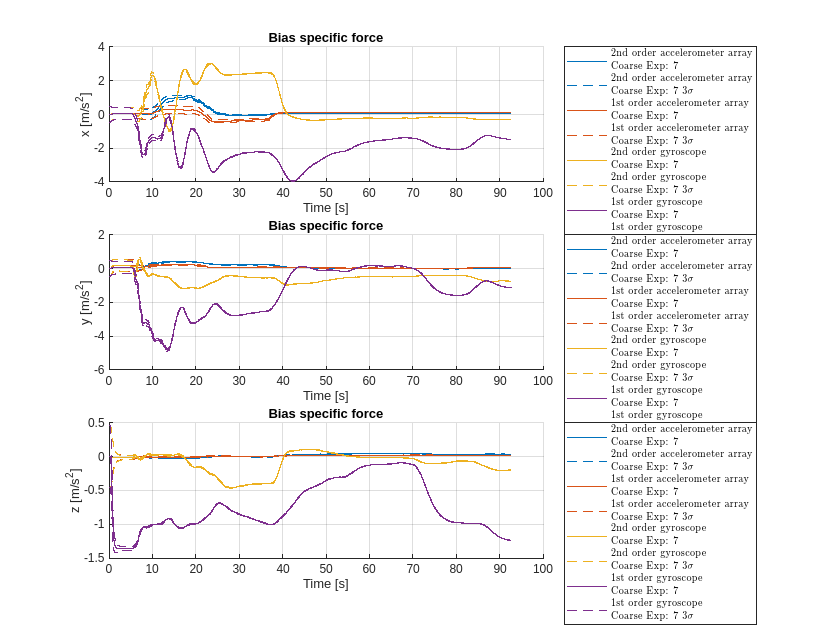

cases_plot = ["coarse", "accelerometer_array_2nd_order";
    "coarse", "accelerometer_array_1st_order";
    "coarse", "gyroscope_2nd_order";
    "coarse", "gyroscope_1st_order"];

exp = 7;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "filt"];
[fig,~] = plot_bias_s(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "normal", extras);
scale_figure(fig,1.5);

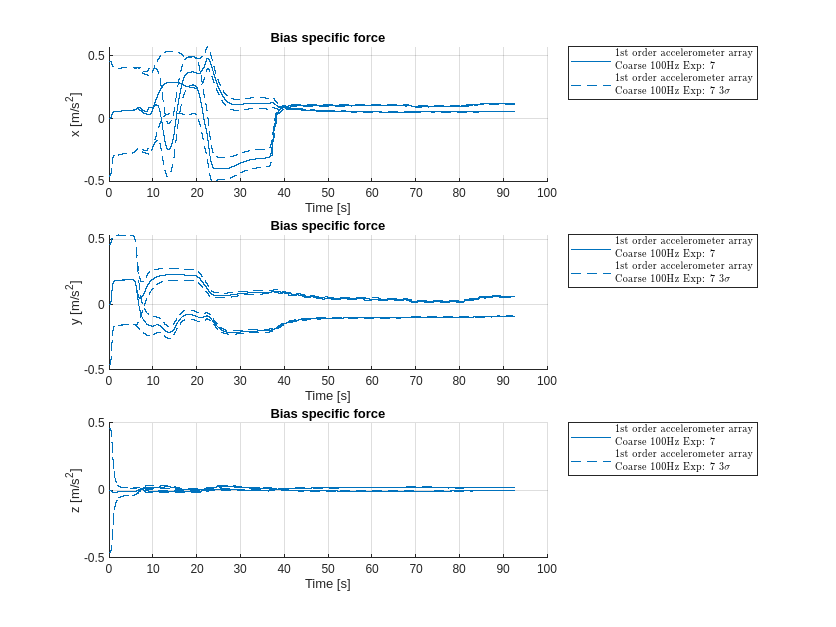

cases_plot = [% "coarse", "accelerometer_array_2nd_order";
     "coarse", "accelerometer_array_1st_order";
%     "coarse", "gyroscope_2nd_order";
%     "coarse", "gyroscope_1st_order";
];

exp = 7;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "filt"];
[fig,ax] = plot_bias_s(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "normal", extras);
% scale_figure(fig,1.5);

cases_plot = [% "coarse_p_100Hz_IMU_100Hz", "accelerometer_array_2nd_order";
     "coarse_p_100Hz_IMU_100Hz", "accelerometer_array_1st_order";
%     "coarse_p_100Hz_IMU_100Hz", "gyroscope_2nd_order";
%     "coarse_p_100Hz_IMU_100Hz", "gyroscope_1st_order";
];
% cases_plot = ["coarse", "accelerometer_array_1st_order"];
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "filt"];
extras.figure = fig;
extras.axes = ax;
plot_bias_s(resSingle{exp}, data_IMU_mc_frame_sliced_100Hz{exp}.time, cases_plot, plotOpt_k, "normal", extras);
scale_figure(fig,1.5);

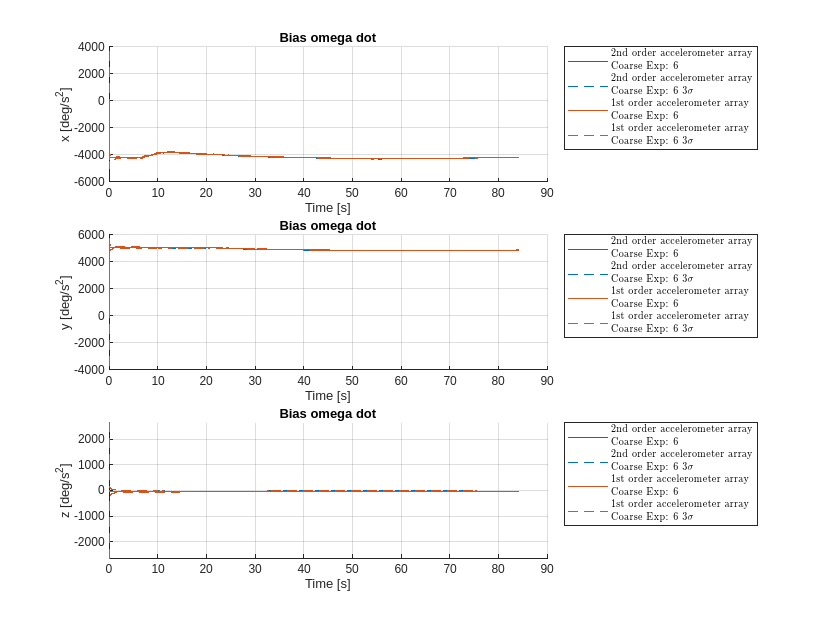

cases_plot = ["coarse", "accelerometer_array_2nd_order";
    "coarse", "accelerometer_array_1st_order"];

exp = 6;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "filt"];
[fig,~] = plot_bias_omega_dot(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "normal", extras);
scale_figure(fig,1.5);

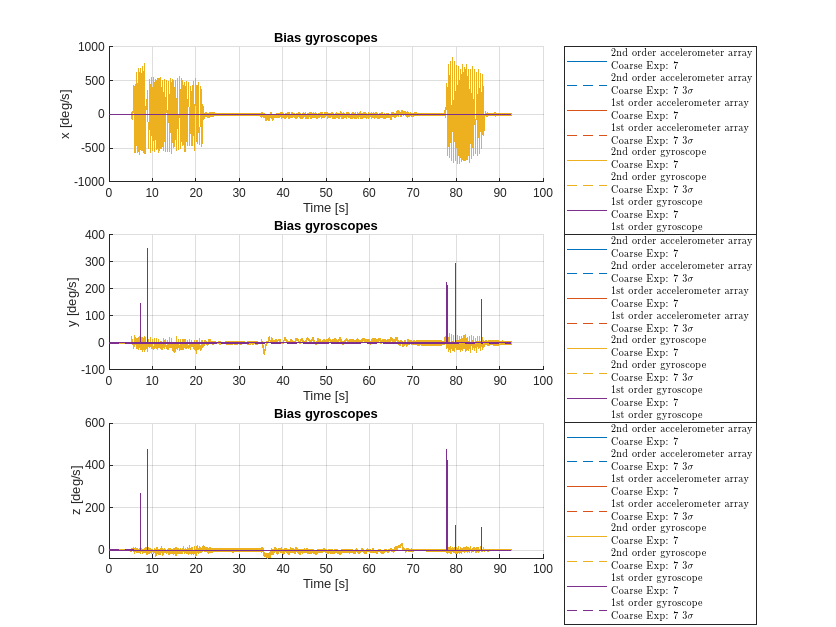

cases_plot = ["coarse", "accelerometer_array_2nd_order";
    "coarse", "accelerometer_array_1st_order";
    "coarse", "gyroscope_2nd_order";
    "coarse", "gyroscope_1st_order"];

exp = 7;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "filt"];
[fig,~] = plot_bias_gyroscopes(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "normal", extras);
scale_figure(fig,1.5);

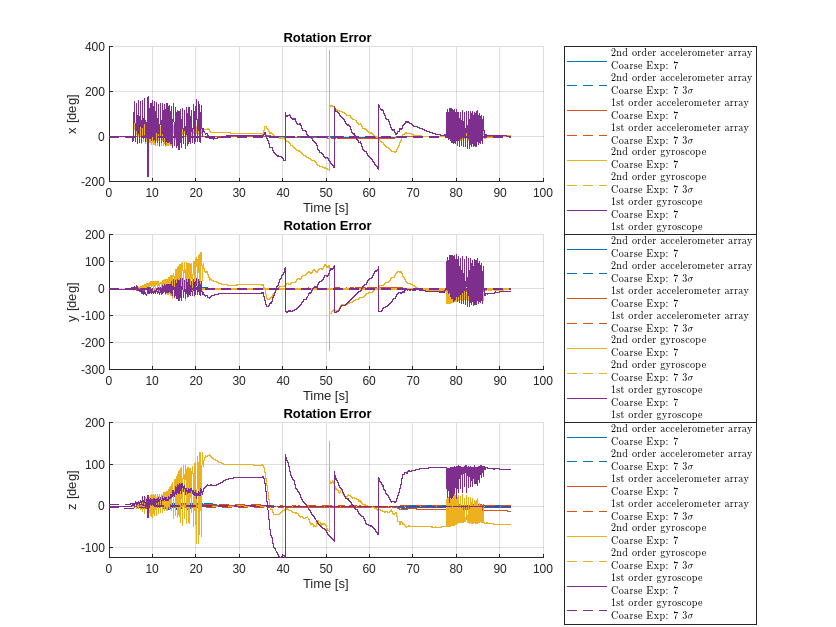

cases_plot = ["coarse", "accelerometer_array_2nd_order";
    "coarse", "accelerometer_array_1st_order";
    "coarse", "gyroscope_2nd_order";
    "coarse", "gyroscope_1st_order"];

exp = 7;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "err"];
[fig,~] = plot_rotation(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "error", extras);
scale_figure(fig,1.5);

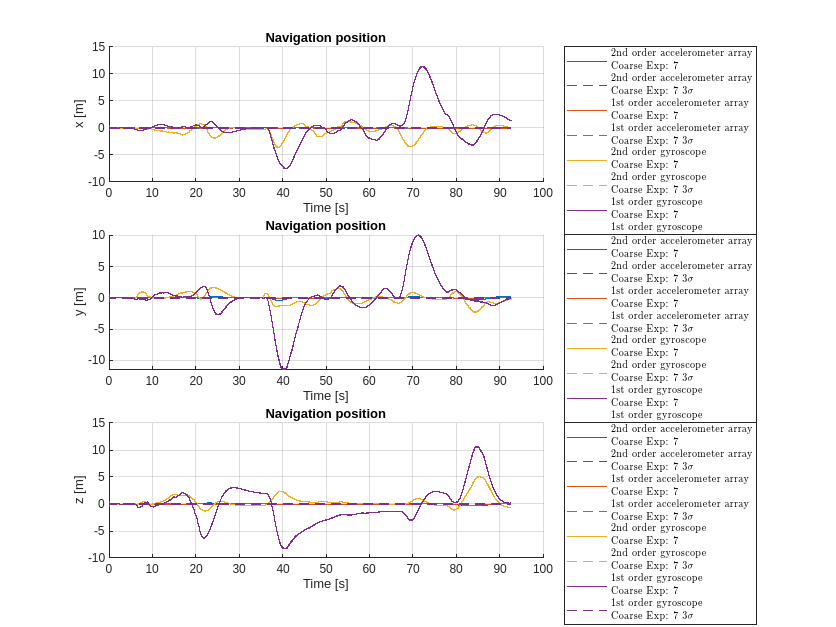

cases_plot = ["coarse", "accelerometer_array_2nd_order";
    "coarse", "accelerometer_array_1st_order";
    "coarse", "gyroscope_2nd_order";
    "coarse", "gyroscope_1st_order"];

exp = 7;
plotOpt_k = struct;
extras = struct;
extras.path = ["res", "err"];
[fig,~] = plot_navigation_position(resSingle{exp}, data_IMU_mc_frame_sliced{exp}.time, cases_plot, plotOpt_k, "error", extras);
scale_figure(fig,1.5);

### Calculate MSE in roll 2

res_roll_2 = cell(N_exp,1);
for exp = 1:N_exp
    % release_times_roll_2 = 62:0.1:64
    res_roll_2{exp} = get_release_inds(data_IMU_mc_frame_sliced{exp}.time, data_R0_t_shift{exp}.release_times_roll_2, 5, settings_default.T);
end
    

resRmseRoll2 = cell(N_exp,1);
for exp = 1:N_exp
    resRmseRoll2{exp}.coarse.label = resSingle{exp}.coarse.label;
    resRmseRoll2{exp}.coarse.accelerometer_array_2nd_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_2nd_order, S_ref{exp}, res_roll_2{exp}.inds_growth);
    resRmseRoll2{exp}.coarse.accelerometer_array_1st_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_1st_order, S_ref{exp}, res_roll_2{exp}.inds_growth);
    resRmseRoll2{exp}.coarse.gyroscope_2nd_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_2nd_order, S_ref{exp}, res_roll_2{exp}.inds_growth);
    try
        resRmseRoll2{exp}.coarse.gyroscope_1st_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_1st_order, S_ref{exp}, res_roll_2{exp}.inds_growth);
    catch
        disp ''
    end
end

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 39311
Size of input vector: 96
Number of gyroscope updates: 39311
Number of position updates: 7863
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 39311
Size of input vector: 96
Number of gyroscope updates: 39311
Number of position updates: 7863
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 0.0e+00 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 39311
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7863
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02
		bia

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 39311
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7863
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 12
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation:  [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_s) [m/s^2]
		   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   8.8e-02   0.0e+00
		   0.0e+00   0.0e+00   8.8e-02
		bias specific force: [m/s^2]
		   1.8e-08   0.0e+00   0.0e+00
		   0.0e+00   1.8e-08   0.0e+00
		   0.0e+00   0.0e+00   1.8e-08
		[m/s^2]
		Start of accelerometer triad measurements:
		       0.1        0.2        0.1
		       0.5        0.4        0.4
		      10.1       10.0       10.0
		Start of 

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 36569
Size of input vector: 96
Number of gyroscope updates: 36569
Number of position updates: 7314
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 36569
Size of input vector: 96
Number of gyroscope updates: 36569
Number of position updates: 7314
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 0.0e+00 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 36569
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7314
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02
		bia

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 36569
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7314
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 12
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation:  [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_s) [m/s^2]
		   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   8.8e-02   0.0e+00
		   0.0e+00   0.0e+00   8.8e-02
		bias specific force: [m/s^2]
		   1.8e-08   0.0e+00   0.0e+00
		   0.0e+00   1.8e-08   0.0e+00
		   0.0e+00   0.0e+00   1.8e-08
		[m/s^2]
		Start of accelerometer triad measurements:
		       0.2        0.1        0.2
		       0.5        0.5        0.5
		      10.1       10.1       10.1
		Start of 

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 37820
Size of input vector: 96
Number of gyroscope updates: 37820
Number of position updates: 7564
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 37820
Size of input vector: 96
Number of gyroscope updates: 37820
Number of position updates: 7564
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 0.0e+00 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 37820
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7564
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02
		bia

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 37820
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7564
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 12
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation:  [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_s) [m/s^2]
		   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   8.8e-02   0.0e+00
		   0.0e+00   0.0e+00   8.8e-02
		bias specific force: [m/s^2]
		   1.8e-08   0.0e+00   0.0e+00
		   0.0e+00   1.8e-08   0.0e+00
		   0.0e+00   0.0e+00   1.8e-08
		[m/s^2]
		Start of accelerometer triad measurements:
		       0.2        0.1        0.1
		       0.4        0.3        0.4
		      10.1       10.0       10.1
		Start of 

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 50041
Size of input vector: 96
Number of gyroscope updates: 50041
Number of position updates: 10009
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00 

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 50041
Size of input vector: 96
Number of gyroscope updates: 50041
Number of position updates: 10009
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 0.0e+00 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00 

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 50041
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 10009
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02
		bi

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 50041
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 10009
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 12
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation:  [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_s) [m/s^2]
		   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   8.8e-02   0.0e+00
		   0.0e+00   0.0e+00   8.8e-02
		bias specific force: [m/s^2]
		   1.8e-08   0.0e+00   0.0e+00
		   0.0e+00   1.8e-08   0.0e+00
		   0.0e+00   0.0e+00   1.8e-08
		[m/s^2]
		Start of accelerometer triad measurements:
		       0.2        0.2        0.1
		       0.7        0.7        0.6
		      10.0       10.0       10.1
		Start of

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 38713
Size of input vector: 96
Number of gyroscope updates: 38713
Number of position updates: 7743
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 38713
Size of input vector: 96
Number of gyroscope updates: 38713
Number of position updates: 7743
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 21
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 0.0e+00 [s]
Propagate rotation: 1
Propagate omega: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias alpha: 1
Propagate bias gyro: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00  

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 38713
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7743
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 15
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation: 4.0e-06 [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_alpha) [mixed units]
		   1.2e+01   1.6e-16  -3.2e-18   0.0e+00   0.0e+00   0.0e+00
		   0.0e+00   1.2e+01  -1.2e-18   0.0e+00   0.0e+00  -5.6e-19
		   0.0e+00   0.0e+00   8.9e+00   0.0e+00   3.9e-19  -7.6e-38
		   0.0e+00   0.0e+00   0.0e+00   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02   3.4e-55
		   0.0e+00   0.0e+00   0.0e+00   0.0e+00   0.0e+00   8.8e-02
		bia

Run Discrete Lie-Group EKF Inertial Navigation v4
Number of time-sample: 38713
Size of input vector: 99
Number of gyroscope updates: 0
Number of position updates: 7743
Number of rotation updates: 0
Number of ZUPTs: 0
Save full covariances: 1
Save prediction: 0
Save auxillary variables: 0
Save jacobians: 0
Size Nx: 15
Size Nw: 12
Sampling time: 2.00e-03 [s]
Sampling freq: 500.0 [Hz]
T2 for rotation:  [s]
Propagate rotation: 1
Propagate position: 1
Propagate velocity: 1
Propagate bias gyro: 1
Propagate bias specific force: 1
Propagation data:
	Accelerometer data:
		white noise chol(Q_s) [m/s^2]
		   8.8e-02   0.0e+00   0.0e+00
		   0.0e+00   8.8e-02   0.0e+00
		   0.0e+00   0.0e+00   8.8e-02
		bias specific force: [m/s^2]
		   1.8e-08   0.0e+00   0.0e+00
		   0.0e+00   1.8e-08   0.0e+00
		   0.0e+00   0.0e+00   1.8e-08
		[m/s^2]
		Start of accelerometer triad measurements:
		       0.2        0.1        0.2
		       0.5        0.4        0.4
		      10.0       10.2       10.1
		Start of 

Unrecognized field name "R".

Error in run_script>run_error_growth (line 1205)
    errors_R(:,:,n) = res_n.res.err.mean.R';

res_roll_2_100Hz = cell(N_exp,1);
for exp = 1:N_exp
    % release_times_roll_2 = 62:0.1:64
    res_roll_2_100Hz{exp} = get_release_inds(data_IMU_mc_frame_sliced_100Hz{exp}.time, data_R0_t_shift{exp}.release_times_roll_2, 5, 1/100);
end
for exp = 1:N_exp
    resRmseRoll2{exp}.coarse_p_100Hz_IMU_100Hz.label = resSingle{exp}.coarse_p_100Hz_IMU_100Hz.label;
    resRmseRoll2{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_2nd_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_2nd_order, S_ref_100Hz{exp}, res_roll_2_100Hz{exp}.inds_growth);
    resRmseRoll2{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_1st_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_1st_order, S_ref_100Hz{exp}, res_roll_2_100Hz{exp}.inds_growth);
    resRmseRoll2{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_2nd_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_2nd_order, S_ref_100Hz{exp}, res_roll_2_100Hz{exp}.inds_growth);
    resRmseRoll2{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_1st_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_1st_order, S_ref_100Hz{exp}, res_roll_2_100Hz{exp}.inds_growth);
end

% cases_plot = ["coarse", "accelerometer_array_2nd_order"];
% cases_plot = ["coarse", "accelerometer_array_1st_order"];
% cases_plot = ["coarse", "gyroscope_2nd_order"];
% cases_plot = ["coarse", "gyroscope_1st_order"];
% cases_plot = ["coarse", "accelerometer_array_1st_order"; "coarse", "gyroscope_1st_order"];
cases_plot = ["coarse", "accelerometer_array_2nd_order"; "coarse", "gyroscope_1st_order"];

exp = 7;
IN_error_position(resRmseRoll2{exp}, res_roll_2{exp}.IN_time_array, cases_plot, struct);

### Plots

cases_plot = ["coarse", "accelerometer_array_2nd_order";
   "coarse",  "accelerometer_array_1st_order";
  "coarse",  "gyroscope_2nd_order";
 "coarse",  "gyroscope_1st_order"];
plotOpt_k = struct;
plotOpt_k.gyroscope_1st_order.ls = "--";
exp = 7;
[fig, ~] = plot_statistics_position(resRmseRoll2{exp}, res_roll_2{exp}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,1.1);

cases_plot = ["coarse_p_100Hz_IMU_100Hz", "accelerometer_array_2nd_order";
   "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
  "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
 "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];
plotOpt_k = struct;
plotOpt_k.gyroscope_1st_order.ls = "--";
exp = 7;
[fig, ~] = plot_statistics_position(resRmseRoll2{exp}, res_roll_2_100Hz{exp}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,1.1);

resRmseRoll2Merged = struct;
resRmseRoll2Merged.coarse = merge_experiments(resRmseRoll2, "coarse");
resRmseRoll2Merged.coarse.label = "Coarse";

resRmseRoll2Merged.coarse_p_100Hz_IMU_100Hz = merge_experiments(resRmseRoll2, "coarse_p_100Hz_IMU_100Hz");
resRmseRoll2Merged.coarse_p_100Hz_IMU_100Hz.label = "Coarse 100Hz";


cases_plot = ["coarse",  "accelerometer_array_2nd_order";
    "coarse",  "accelerometer_array_1st_order";
    "coarse",  "gyroscope_2nd_order";
    "coarse",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;

[fig, ~] = plot_statistics_position(resRmseRoll2Merged, res_roll_2{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,2.0);

cases_plot = ["coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;

[fig, ~] = plot_statistics_position(resRmseRoll2Merged, res_roll_2_100Hz{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,2.0);


#### Make figure for paper 


resRmseRoll2Merged.coarse.label = "";
cases_plot = ["coarse",  "accelerometer_array_2nd_order";
    "coarse",  "accelerometer_array_1st_order";
    "coarse",  "gyroscope_2nd_order";
    "coarse",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_array_2nd_order.m = "+";
plotOpt_k.accelerometer_array_2nd_order.m_offset = 1;
plotOpt_k.accelerometer_array_2nd_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;
extras = struct;
extras.legend = {"Location","northwest","NumColumns",1, 'Interpreter',"latex"};
extras.omit_title = true;
[fig, ax] = plot_statistics_position(resRmseRoll2Merged, res_roll_2{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all", extras);
set(ax,"YScale","log")
printpdf_multiple(fig, filePrefix + "high_dynamics_high_Fs.pdf", foldersFigs)


resRmseRoll2Merged.coarse_p_100Hz_IMU_100Hz.label = "";
cases_plot = ["coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_array_2nd_order.m = "+";
plotOpt_k.accelerometer_array_2nd_order.m_offset = 1;
plotOpt_k.accelerometer_array_2nd_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;
extras = struct;
extras.legend = {"Location","northwest","NumColumns",1, 'Interpreter',"latex"};
extras.omit_title = true;
[fig, ax] = plot_statistics_position(resRmseRoll2Merged, res_roll_2_100Hz{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all", extras);
set(ax,"YScale","log")
printpdf_multiple(fig, filePrefix + "high_dynamics_low_Fs.pdf", foldersFigs)


### Calculate MSE in Middle Phase

res_roll_middle = cell(N_exp,1);
for exp = 1:N_exp
    % release_times_roll_2 = 62:0.1:64
    res_roll_middle{exp} = get_release_inds(data_IMU_mc_frame_sliced{exp}.time, data_R0_t_shift{exp}.release_times_middle, 5, settings_default.T);
end
    

resRmseMiddle = cell(N_exp,1);
for exp = 1:N_exp
    resRmseMiddle{exp}.coarse.label = resSingle{exp}.coarse.label;
    resRmseMiddle{exp}.coarse.accelerometer_array_2nd_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_2nd_order, S_ref{exp}, res_roll_middle{exp}.inds_growth);
    resRmseMiddle{exp}.coarse.accelerometer_array_1st_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.accelerometer_array_1st_order, S_ref{exp}, res_roll_middle{exp}.inds_growth);
    resRmseMiddle{exp}.coarse.gyroscope_2nd_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_2nd_order, S_ref{exp}, res_roll_middle{exp}.inds_growth);
    resRmseMiddle{exp}.coarse.gyroscope_1st_order = run_error_growth(sensorData{exp}.raw_100Hz, init{exp}, simdata.coarse.gyroscope_1st_order, S_ref{exp}, res_roll_middle{exp}.inds_growth);
end

res_roll_middle_100Hz = cell(N_exp,1);
for exp = 1:N_exp
    % release_times_roll_2 = 62:0.1:64
    res_roll_middle_100Hz{exp} = get_release_inds(data_IMU_mc_frame_sliced_100Hz{exp}.time, data_R0_t_shift{exp}.release_times_middle, 5, 1/100);
end
for exp = 1:N_exp
    resRmseMiddle{exp}.coarse_p_100Hz_IMU_100Hz.label = resSingle{exp}.coarse_p_100Hz_IMU_100Hz.label;
    resRmseMiddle{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_2nd_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_2nd_order, S_ref_100Hz{exp}, res_roll_middle_100Hz{exp}.inds_growth);
    resRmseMiddle{exp}.coarse_p_100Hz_IMU_100Hz.accelerometer_array_1st_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.accelerometer_array_1st_order, S_ref_100Hz{exp}, res_roll_middle_100Hz{exp}.inds_growth);
    resRmseMiddle{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_2nd_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_2nd_order, S_ref_100Hz{exp}, res_roll_middle_100Hz{exp}.inds_growth);
    resRmseMiddle{exp}.coarse_p_100Hz_IMU_100Hz.gyroscope_1st_order = run_error_growth(sensorData{exp}.raw_p_100Hz_IMU_100Hz, init{exp}, simdata.coarse_100Hz.gyroscope_1st_order, S_ref_100Hz{exp}, res_roll_middle_100Hz{exp}.inds_growth);
end

% cases_plot = ["coarse", "accelerometer_array_2nd_order"];
% cases_plot = ["coarse", "accelerometer_array_1st_order"];
% cases_plot = ["coarse", "gyroscope_2nd_order"];
% cases_plot = ["coarse", "gyroscope_1st_order"];
cases_plot = ["coarse", "accelerometer_array_1st_order"; "coarse", "gyroscope_1st_order"];
exp = 1;
IN_error_position(resRmseMiddle{exp}, res_roll_middle{exp}.IN_time_array, cases_plot, struct);


cases_plot = ["coarse",  "accelerometer_array_2nd_order";
   "coarse",  "accelerometer_array_1st_order";
  "coarse",  "gyroscope_2nd_order";
 "coarse",  "gyroscope_1st_order"];
plotOpt_k = struct;
plotOpt_k.gyroscope_1st_order.ls = "--";
[fig, ~] = plot_statistics_position(resRmseMiddle{exp}, res_roll_middle{exp}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,1.1);

cases_plot = ["coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_2nd_order";
   "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
  "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
 "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];
exp = 7;
plotOpt_k = struct;
plotOpt_k.gyroscope_1st_order.ls = "--";
[fig, ~] = plot_statistics_position(resRmseMiddle{exp}, res_roll_middle_100Hz{exp}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,1.1);

resRmseMiddleMerged = struct;
resRmseMiddleMerged.coarse = merge_experiments(resRmseMiddle, "coarse");
resRmseMiddleMerged.coarse.label = "Coarse";

resRmseMiddleMerged.coarse_p_100Hz_IMU_100Hz = merge_experiments(resRmseMiddle, "coarse_p_100Hz_IMU_100Hz");
resRmseMiddleMerged.coarse_p_100Hz_IMU_100Hz.label = "Coarse 100 Hz";



cases_plot = ["coarse",  "accelerometer_array_2nd_order";
    "coarse",  "accelerometer_array_1st_order";
    "coarse",  "gyroscope_2nd_order";
    "coarse",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;

[fig, ~] = plot_statistics_position(resRmseMiddleMerged, res_roll_middle{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,2.0);



cases_plot = ["coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];

plotOpt_k = struct;
plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;

[fig, ~] = plot_statistics_position(resRmseMiddleMerged, res_roll_middle_100Hz{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all");
scale_figure(fig,2.0);


#### Make figure for paper 


cases_plot = ["coarse",  "accelerometer_array_2nd_order";
    "coarse",  "accelerometer_array_1st_order";
    "coarse",  "gyroscope_2nd_order";
    "coarse",  "gyroscope_1st_order"];

resRmseMiddleMerged.coarse.label = "";
plotOpt_k = struct;
plotOpt_k.accelerometer_array_2nd_order.m = "+";
plotOpt_k.accelerometer_array_2nd_order.m_offset = 1;
plotOpt_k.accelerometer_array_2nd_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;
extras = struct;
extras.legend = {"Location","northwest","NumColumns",1, 'Interpreter',"latex"};
extras.omit_title = true;
[fig, ax] = plot_statistics_position(resRmseMiddleMerged, res_roll_middle{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all", extras);
set(ax,"YScale","log")
printpdf_multiple(fig, filePrefix + "low_dynamics_high_Fs.pdf", foldersFigs)


cases_plot = ["coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "accelerometer_array_1st_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_2nd_order";
    "coarse_p_100Hz_IMU_100Hz",  "gyroscope_1st_order"];

resRmseMiddleMerged.coarse_p_100Hz_IMU_100Hz.label = "";
plotOpt_k = struct;
plotOpt_k.accelerometer_array_2nd_order.m = "+";
plotOpt_k.accelerometer_array_2nd_order.m_offset = 1;
plotOpt_k.accelerometer_array_2nd_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_1st_order.m = "+";
plotOpt_k.accelerometer_gyroscope_1st_order.m_offset = 10;
plotOpt_k.accelerometer_gyroscope_1st_order.m_space = 100;

plotOpt_k.accelerometer_array_1st_order.m = "+";
plotOpt_k.accelerometer_array_1st_order.m_offset = 30;
plotOpt_k.accelerometer_array_1st_order.m_space = 100;

plotOpt_k.accelerometer_gyroscope_2nd_order.m = "+";
plotOpt_k.accelerometer_gyroscope_2nd_order.m_offset = 50;
plotOpt_k.accelerometer_gyroscope_2nd_order.m_space = 100;
extras = struct;
extras.legend = {"Location","northwest","NumColumns",1, 'Interpreter',"latex"};
extras.omit_title = true;
[fig, ax] = plot_statistics_position(resRmseMiddleMerged, res_roll_middle_100Hz{1}.IN_time_array, cases_plot, plotOpt_k,"rmse-all", extras);
set(ax,"YScale","log")
printpdf_multiple(fig, filePrefix + "low_dynamics_low_Fs.pdf", foldersFigs)

## Save data for paper figures


pathDataFigsPaper = fullfile(pathScript,"data_figs_paper")
mkdir(pathDataFigsPaper)

resRmseRoll2Cond = compute_rmse_pos(resRmseRoll2Merged);
resRmseMiddleCond = compute_rmse_pos(resRmseMiddleMerged);
res_roll_middle_100Hz_time = res_roll_middle_100Hz{1}.IN_time_array;
res_roll_middle_500Hz_time = res_roll_middle{1}.IN_time_array;
res_roll_2_500Hz_time = res_roll_2{1}.IN_time_array;
res_roll_2_100Hz_time = res_roll_2_100Hz{1}.IN_time_array;
save(fullfile(pathDataFigsPaper,"data.mat"), ...
    "resRmseRoll2Cond", "resRmseMiddleCond",...
    "res_roll_middle_100Hz_time",...
    "res_roll_middle_500Hz_time",...
    "res_roll_2_500Hz_time",...
    "res_roll_2_100Hz_time")

## Functions

function S_out = compute_rmse_pos(S_in)


S_out = struct;
fields_1 = fieldnames(S_in);
for f_i = 1:numel(fields_1)
    % Coarse
    f_1 = fields_1{f_i};
    if strcmp(f_1, "label")
        continue
    end
    S_in_1 = S_in.(f_1);
    fields_2 = fieldnames(S_in_1);
    for f_j = 1:numel(fields_2)
        % Acc array 
        f_2 = fields_2{f_j};
        if strcmp(f_2, "label")
            continue
        end
        p = S_in_1.(f_2).p;
        p = reshape(p, size(p,1),[]);
        p_rmse = sqrt(mean(p.^2,2));
        S_out.(f_1).(f_2) = p_rmse;
    end

end

end

### Execution

function [c, misc] = run_filter(sensorData, init, simdata, run_settings, S_ref, x, f_change, mask_logLL)

if nargin < 4
    run_settings = struct;
end

if isfield(run_settings, "verbose")
    simdata.verbose = run_settings.verbose;
end
if nargin > 5
    [sensorData, init, simdata, changes] = f_change(x, sensorData, init, simdata);
end
model = simdata.get_model(simdata);

res = DLGEKFv4(sensorData, init, model, simdata);

if isfield(run_settings, "compute_error") && nargin > 4
    res.err = compute_error_tot(res, S_ref);
end

misc = struct;
misc.res = res;
if isfield(run_settings, "save_input") && run_settings.save_input
    misc.sensorData = sensorData;
    misc.init = init;
    misc.simdata = simdata;
    misc.model = model;
end

if nargin > 5
    misc.changes = changes;
end

o = 0; % Offset in ind
% Depends on in the order of measurement updates in filter
save_residuals = isfield(run_settings, "save_residuals") && run_settings.save_residuals;

if isfield(sensorData, "gyro_measurements") && simdata.do_gyro_updates && save_residuals 
    mask = all(~isnan(sensorData.gyro_measurements));
    e = res.logL.residuals_normalized(mask);
    e_gyro = cellfun(@(e_i) e_i(1:3), e(2:end), 'UniformOutput', false); % Skip initial value
    misc.e_gyro = cat(2, e_gyro{:});
    o = o + 3;
end

if isfield(sensorData, "position_measurements") && simdata.do_position_updates && save_residuals
    inds = (1:3) + o;
    mask = all(~isnan(sensorData.position_measurements));
    e = misc.res.logL.residuals_normalized(mask);
    e_pos = cellfun(@(e_i) e_i(inds), e(2:end), 'UniformOutput', false); % Skip initial value
    misc.e_pos = cat(2, e_pos{:});
    o = o + 3;
end

if isfield(sensorData, "rotation_measurements") && simdata.do_rotation_updates && save_residuals
    inds = (1:3) + o;
    mask = reshape(all(~isnan(sensorData.rotation_measurements),[1 2]),[],1);
    e = misc.res.logL.residuals_normalized(mask);
    e_rot = cellfun(@(e_i) e_i(inds), e(2:end), 'UniformOutput', false); % Skip initial value
    misc.e_rot = cat(2, e_rot{:});
end

use_mask_logLL = isfield(run_settings, "use_mask_logLL") && run_settings.use_mask_logLL;
if nargin > 7 && use_mask_logLL
    % Assume first time point is included
    parts = res.logL.parts(mask_logLL);
    % Skip first time-point
    logL = -1/2*sum(parts(2:end));
    c = -logL;
else
    c = -res.logL.value;
end

end

function err = compute_error_tot(S_tot, S_ref)

err = struct;
err.mean = compute_error(S_tot.filt.mean, S_ref);

% Copy standard deviations
fields = fieldnames(err.mean);
for idx = 1:length(fields)
    err.std.(fields{idx}) = S_tot.filt.std.(fields{idx});
end

end

#### run_error_growth

function [errors, misc] = run_error_growth(sensorData, init, simdata, S_ref, inds_growth, x, f_change, run_settings_in)

if nargin > 7
    run_settings = run_settings_in;
else
    run_settings = struct;
    run_settings.save_input = false;
    run_settings.save_residuals = false;
    run_settings.verbose = true;
    run_settings.compute_error = false;
end

% Run whole sequence
simdata.save_full_covariances = true;
simdata.verbose = true;

if nargin == 5
    f_change = @change_nothing;
    x = 0;
end
% run_filter(sensorData, init, simdata, run_settings, S_ref, x, f_change)
[~, res_tot] = run_filter(sensorData, init, simdata, run_settings, S_ref, x, f_change);
% res_tot = run_filter(sensorData, initData, my_settings, S_ref, myFilter);

x_tot = res_tot.res.tot.filt.x;
R_tot = res_tot.res.tot.filt.R;
P_tot = res_tot.res.tot.filt.P;

[N_time_samples, N_trails] = size(inds_growth);

init_tot = cell(N_trails,1);
sensorData_tot = cell(N_trails,1);
S_ref_tot = cell(N_trails,1);

% Prepare for parts
for n = 1:N_trails
    inds_n = inds_growth(:,n);
    inds_start = inds_n(1);
    
    init_n = struct;
    init_n.x = x_tot(:,inds_start);
    init_n.R = R_tot(:,:,inds_start);
    init_n.P = P_tot(:,:,inds_start);
    init_tot{n} = init_n;

    sensorData_n = sensorData;
    sensorData_n.acc_measurements = sensorData.acc_measurements(:,inds_n);
    sensorData_n.gyro_measurements = sensorData.gyro_measurements(:,inds_n);
    
    
    assert(isfield(sensorData_n,"position_measurements"))
    sensorData_n = rmfield(sensorData_n,"position_measurements");
    assert(~isfield(sensorData_n,"position_measurements"))

    if isfield(sensorData_n,"rotation_updates")
        sensorData_n = rmfield(sensorData_n,"rotation_updates");
    end
    sensorData_tot{n} = sensorData_n;
    
    S_ref_n = struct;
    S_ref_n.p = S_ref.p(:,inds_n);
    
    if isfield(S_ref,"R")
        S_ref_n.R = S_ref.R(:,:,inds_n);
    end
    S_ref_tot{n} = S_ref_n;
end

run_settings_parfor = struct;
run_settings_parfor.save_input = false;
run_settings_parfor.save_residuals = false;
run_settings_parfor.verbose = false;
run_settings_parfor.compute_error = true;

simdata_parfor = simdata;
simdata_parfor.save_full_covariances = false;
simdata_parfor.verbose = false;

res_parts = cell(N_trails,1);
errors_p = zeros(N_time_samples,3, N_trails);
errors_R = zeros(N_time_samples,3, N_trails);

for n = 1:N_trails    
    [~,res_n] = run_filter(sensorData_tot{n}, init_tot{n}, simdata_parfor, run_settings_parfor, S_ref_tot{n}, x, f_change);
    res_parts{n} = res_n;
    errors_p(:,:,n) = res_n.res.err.mean.p';
    errors_R(:,:,n) = res_n.res.err.mean.R';
   
end
errors = struct;
errors.p = errors_p;
errors.R = errors_R;
errors.label = simdata.label;

misc = struct;
misc.res_tot = res_tot;
misc.res_parts = res_parts;


end


function [sensorData, init, simdata, res] = change_nothing(~, sensorData, init, simdata)
res = struct;
end

#### run_error_growth_tot

% Stich together all the trajectories
function [res] = run_error_growth_tot(time_tot, sensorData, initData, my_settings, S_ref, myFilter, inds_growth)

[~, N_trails] = size(inds_growth);

res = cell(N_trails,1);

[~, misc] = run_error_growth(sensorData, initData, my_settings, S_ref, myFilter, inds_growth);

for n = 1:N_trails
    inds_n = inds_growth(:,n);
    inds_start = inds_n(1);
    
    for c = ["filt", "pred", "err"]
        for t = ["p"]
            res{n}.(c).(t) = cat(2,misc.res_tot.(c).(t)(:,1:inds_start-1), misc.res_parts{n}.(c).(t));
        end
    end    
    res{n}.time = time_tot(1:inds_n(end));
end

end

function [res,misc] = estimate_acc_bias_filter(sensorData, initImu, settings_default, S_ref)

settings_default.verbose = false;
misc = cell(settings_default.N_a,1);
inds_IMU = reshape(1:settings_default.N_a*3, 3, []);


for k = 1:settings_default.N_a
    sensorData_k = sensorData;
    kk = inds_IMU(:,k);
    sensorData_k.u_acc = sensorData.u_acc(kk,:);
    sensorData_k.Q_acc = sensorData.Q_acc(kk,kk);
    sensorData_k.Q_bias_acc = zeros(3);

    sensorData_k.u_gyro = sensorData.u_gyro(kk,:);
    sensorData_k.Q_gyro = sensorData.Q_gyro(kk,kk);
    sensorData_k.Q_bias_gyro = zeros(3);
    
    
    misc{k} = run_filter(sensorData_k, initImu, settings_default, S_ref, @DLGEkfClassicIns);
end

res = struct;
res.b_a = zeros(3, settings_default.N_a);
res.b_g = zeros(3, settings_default.N_a);
for k = 1:settings_default.N_a
    res.b_a(:,k) = mean(misc{k}.filt.b_a(:,end-2000),2);    
    res.b_g(:,k) = mean(misc{k}.filt.b_g(:,end-2000),2);    
end

end

function [c, res] = run_Q(x, simdata, sensorData, init)

simdata.verbose = false;
sig_a = x(1);
sig_g = x(2);
sig_p = x(3);
sensorData.Q_acc = sig_a^2*eye(size(sensorData.Q_acc));
sensorData.Q_gyro = sig_g^2*eye(size(sensorData.Q_gyro));
sensorData.Q_pos = sig_p^2*eye(size(sensorData.Q_pos));

model = D_LG_EKF_Array(simdata);

res = DLGEKFv3(sensorData, init, model, simdata);

c = -res.logL.value;

end


function [c, res] = run_opt(x, simdata, sensorData, init, f_change)

simdata.verbose = false;

[sensorData, simdata] = f_change(x, sensorData, simdata);

model = D_LG_EKF_Array(simdata);

res = DLGEKFv3(sensorData, init, model, simdata);

c = -res.logL.value;

end

function [sensorData, simdata] = change_Q_rig_R_r(x, sensorData, simdata)

sig_a = x(1);
sig_g = x(2);
sig_p = x(3);
R_rig = expSO3(x(4:6));
r_rig = x(7:9);

simdata.r = R_rig*simdata.r + r_rig;
N_imu = size(simdata.r,2);
sensorData.u_acc = kron(eye(N_imu), R_rig)*sensorData.u_acc;
sensorData.Q_acc = sig_a^2*eye(size(sensorData.Q_acc));

if isfield(sensorData,"gyro_measurements")
    sensorData.gyro_measurements = R_rig*sensorData.gyro_measurements;
elseif isfield(sensorData,"u_gyro")
    sensorData.u_gyro = R_rig*sensorData.u_gyro;
else
    error("wrong")
end
sensorData.Q_gyro = sig_g^2*eye(size(sensorData.Q_gyro));

sensorData.Q_pos = sig_p^2*eye(size(sensorData.Q_pos));

end

function S_out = merge_experiments(S_in, pa)

S_out = struct;
fields = fieldnames(S_in{1}.(pa));
for f_i = 1:numel(fields)
    f = fields{f_i};
    if strcmp(f, "label")
        continue
    end
    S_out.(f).label = S_in{1}.(pa).(f).label;
    for p = ["p", "R"]
        a = cell(length(S_in),1);
        for k = 1:length(S_in)
            a{k} = S_in{k}.(pa).(f).(p);
        end
        S_out.(f).(p) = cat(3, a{:});
    end
end
end